## **2023AAPS0013P - Kalaman Filter Implementation**

**Pranav Chandra N.V**

-----x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x----

### Generation of Data

Setting Variables

speed = 1

speed = 1

initial = 0

initial = 0

time = 0

time = 0

sim_time = 60

sim_time = 60

timestep = 1

timestep = 1


timesteps = 0:timestep:sim_time

timesteps =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


First generating our data

true_pos = speed*timesteps

true_pos =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


true_vel = speed

true_vel = 1

noise = normrnd(0, sqrt(2), size(timesteps));
velocities = normrnd(1, sqrt(0.02), size(timesteps));
positions = true_pos+noise

positions =     0.7604    3.5935   -1.1945    4.2193    4.4508    3.1506    5.3868    7.4845   13.0606   12.9166    8.0910   15.2920   13.0259   12.9108   15.0108   14.7101   15.8244   19.1068   19.9927   21.0042   20.9496   19.2924   23.0143   25.3055   24.6914   26.4633   27.0280   26.5709   28.4156   27.8866   31.2564   29.3778   30.4884   31.8552   29.8362   37.0342   36.4599   35.9324   39.9379   36.5796   39.8554   40.6585   42.4514   43.4424   42.7769   44.9575   45.7668   47.8877   49.5461   50.5687


-----x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x----

### Implementation of Kalaman Filter

Setting up initial variables and matrices

r = 2; %variance in position - taken from given normal distribution
s = 0.02; %variance in velocity - totally random

vel = 100; %guess
pos = 100; %guess
var_pos_now = 10000; %high variance to allow for fast movement to real value
var_pos_next = 0;
var_vel_now = 100;
var_vel_next = 0;

predictions(61) = [0]

predictions =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


estimations(61) = [pos]

estimations =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Kx_array(61) = [0]

Kx_array =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Kv_array(61) = [0]

Kv_array =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Beginning with the prediciton step

for z=1:1:((sim_time*(1/timestep))+1)
    %state prediction tep
    pos = pos+timestep*velocities(z);
    var_pos_next = var_pos_now+(timestep^2)*var_vel_now;
    velocities(z) = velocities(z);
    var_vel_next = var_vel_now;
    predictions(z) = pos;

    %state updation step
    delta = positions(z)-pos;

    %%predicting position after finding kalaman gain for position Kx
    Kx = (var_pos_next)/(var_pos_next+r); %finding kalaman gain for position
    Kx_array(z) = Kx;
    Kv = (var_vel_next)/(var_vel_next+s); %finding kalaman gain for velocity
    Kv_array(z) = Kv;
    
    pos = pos + Kx*delta;
    var_pos_now = (1-Kx)*var_pos_next;
    vel = vel + Kv*(delta/timestep);
    var_vel_now = (1-Kv)*var_vel_next;

    estimations(z) = pos;
end

Now Plotting the graph of course

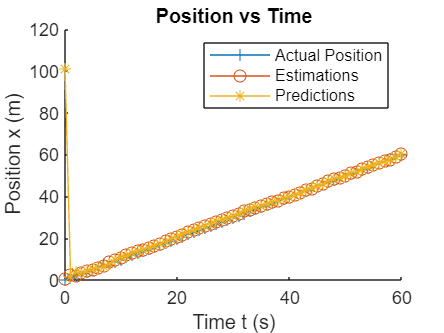

hold on
plot(timesteps, true_pos, '-+')
plot(timesteps, estimations, '-o')
plot(timesteps, predictions, '-*')
legend('Actual Position', 'Estimations', 'Predictions')
xlabel('Time t (s)')
ylabel('Position x (m)')
title('Position vs Time')
hold off

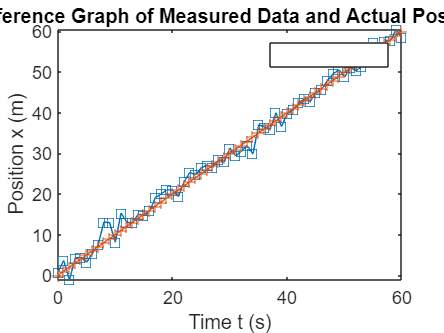


plot(timesteps, positions, '-square', timesteps, true_pos, '-+')
legend('')
xlabel('Time t (s)')
ylabel('Position x (m)')
title('Reference Graph of Measured Data and Actual Position')

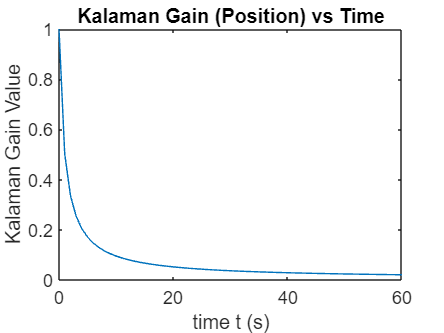


plot(timesteps, Kx_array)
xlabel('time t (s)')
ylabel('Kalaman Gain Value')
title('Kalaman Gain (Position) vs Time')

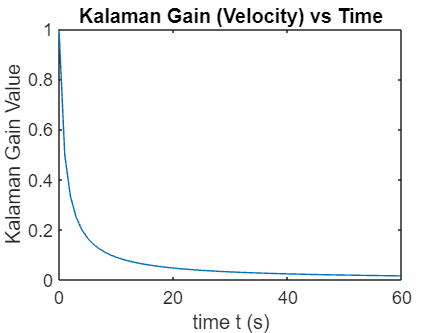


plot(timesteps, Kv_array)
xlabel('time t (s)')
ylabel('Kalaman Gain Value')
title('Kalaman Gain (Velocity) vs Time')